# Rolling and recursize estimation

## Notes

The first block demonstrated how to compute rolling estimates for a single series. This is then used multiple times below with a loop over series to compute the estimates for all 4 series.

- A number of `set` blocks are used with the plotting commands. These set various attributes of plots such as color, line width or line style.

- `axis tight` is used to set the axis to be tight.

- `axis` is then used to set the change the axis to a nice width

- Cell arrays are used to hold title strings. These are good for collections of strings or other objects.

## Setup

Clear and reset the workspace and load required data

% Clean up everything
clear all
close all
clc
% Reset rng to make runs the same
rng('default')
% Load data
load FF_data.mat

## Rolling Regressions for 1 asset

Rolling estimates are just the usual estimate only for a sub-sample of the data, and so a loop is needed.

% Dates, X and y
FF_mldates = c2mdate(FF_factors_monthly(:,1)*100 + 1);
X = FF_factors_monthly(:,2:4);
y = FF_portfolios_monthly(:,2);
% Remove any nan values
pl = any(isnan(X),2);
X = X(~pl,:);
y = y(~pl,:);
% Get the number of data points
T = size(y,1);
% Full sample estimate
b_full_sample = ols(y,X,1);
% Arrays to hold rolling estimates
se_roll = zeros(4,T);
b_roll = zeros(4,T);
% Loop from 60 to the end
for t=60:T
    X_roll = X(t-59:t,:);
    y_roll = y(t-59:t);
    [b_roll(:,t),~,~,~,VCV_white]=ols(y_roll,X_roll,1);
    se_roll(:,t) = sqrt(diag(VCV_white));
end

## Rolling regression estimates for all assets

Implementing for 4 assets requires using the previous code inside loop across assets. This code block also plots the constant beta, the rolling beta as well as some naive confidence intervals.

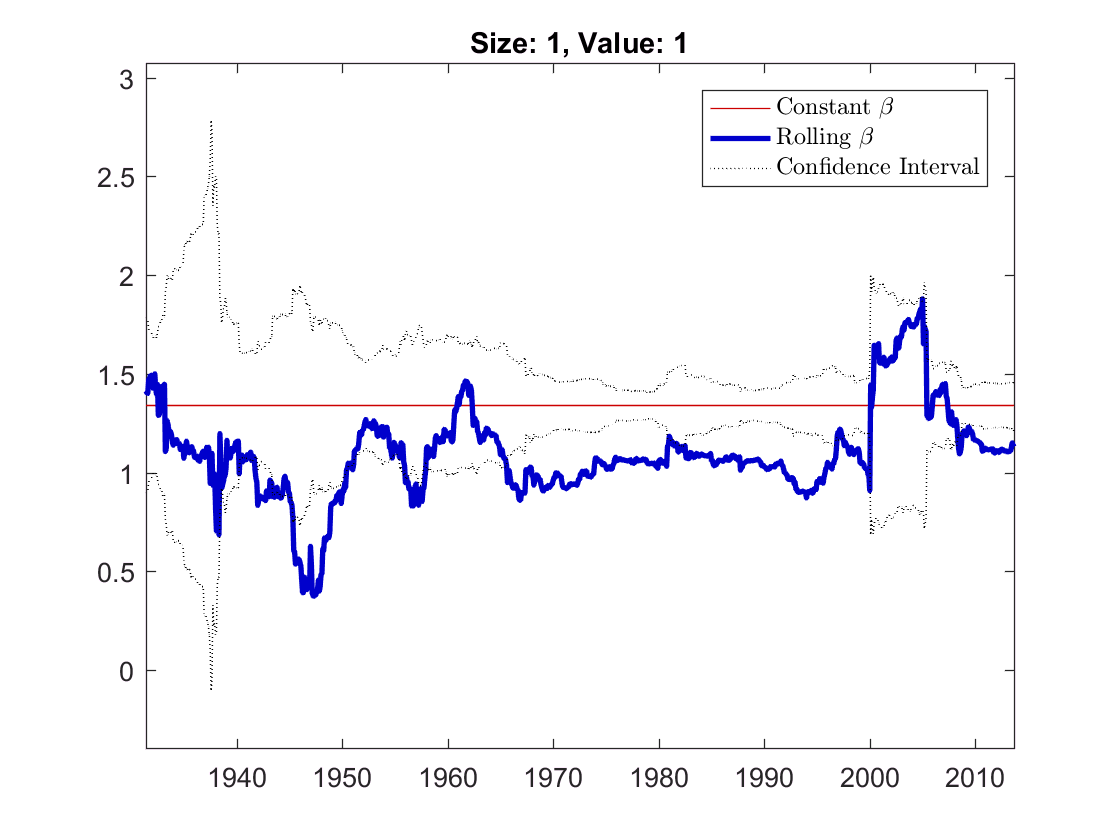

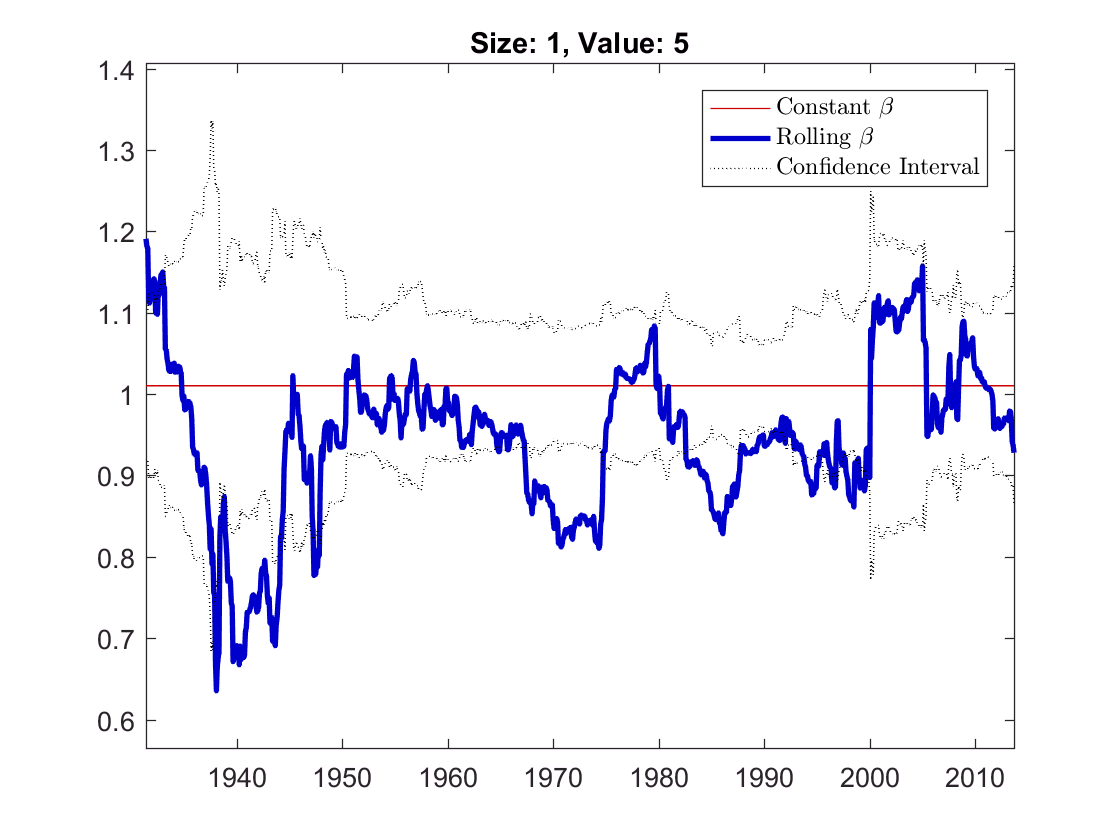

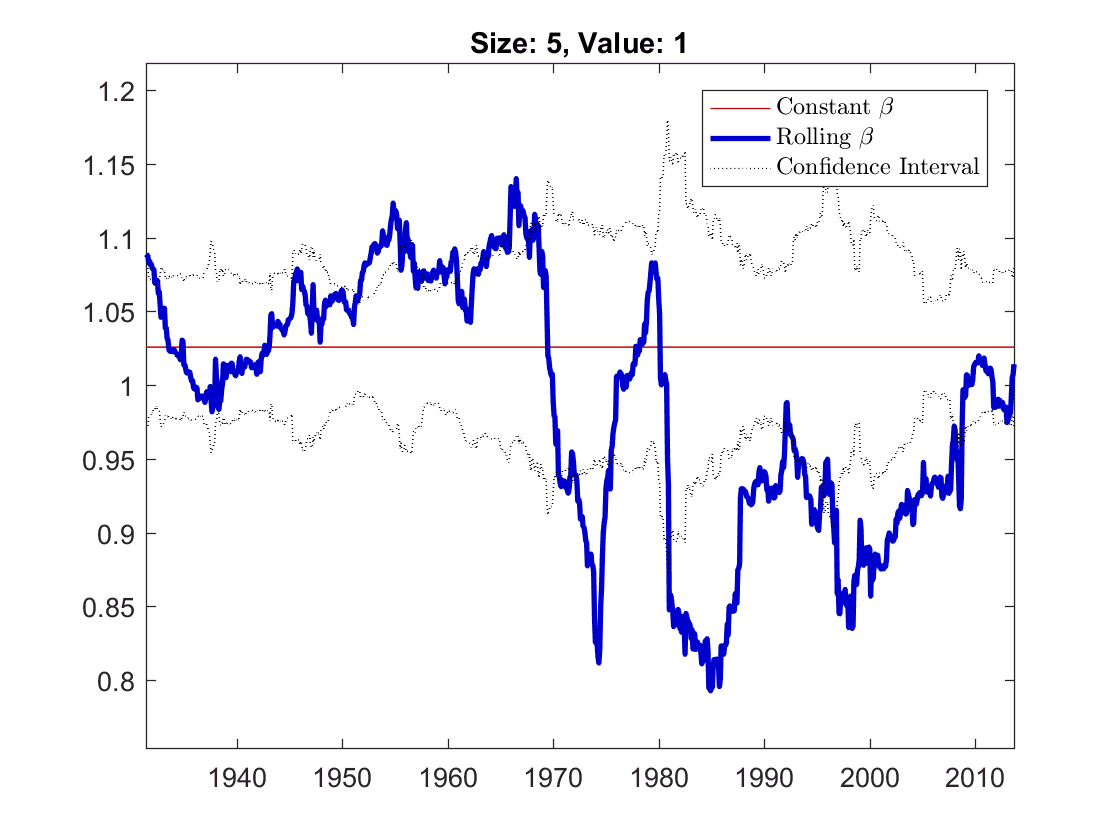

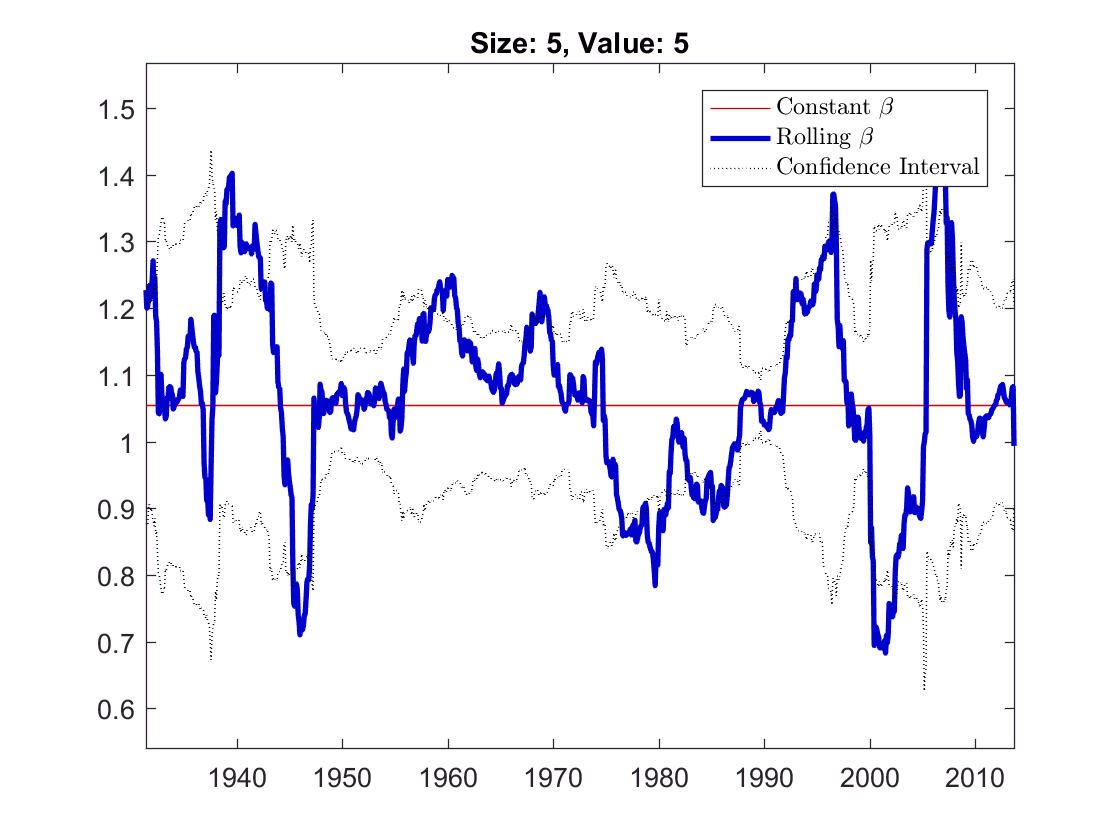

% Array containing all "y" data
ys = FF_portfolios_monthly(:,[2 6 22 26]);
% Remove any nan observations
ys = ys(~pl,:);
% Clean up dates for plotting
FF_mldates = FF_mldates(~pl);
% Set up titles to use in the figures
titles = {'Size: 1, Value: 1','Size: 1, Value: 5','Size: 5, Value: 1','Size: 5, Value: 5'};

% Loop across the 4 series
for i=1:4
    % Get the "y" for a single series
    y = ys(:,i);
    % Full sample estimates
    b_full_sample = ols(y,X,1);
    % Arrays to hold rolling estimates
    se_roll = zeros(4,T);
    b_roll = zeros(4,T);
    % Loop from 60 to the end
    for t=60:T
        X_roll = X(t-59:t,:);
        y_roll = y(t-59:t);
        [b_roll(:,t),~,~,~,VCV_white]=ols(y_roll,X_roll,1);
        se_roll(:,t) = sqrt(diag(VCV_white));
    end
    % Compute beta +/- the confidence interval, market only
    b_ci_plus = b_full_sample(2) + 1.96*se_roll(2,:);
    b_ci_minus = b_full_sample(2) - 1.96*se_roll(2,:);
    
    figure(i)
    
    plot_data = [b_full_sample(2)*ones(T,1) b_roll(2,:)' b_ci_plus' b_ci_minus'];
    % Remove first 59 points, which are 0
    plot_data = plot_data(60:end,:);
    % Do the same for the dates
    dates = FF_mldates(60:end);
    % Plot the data
    h = plot(dates,plot_data);
    % This sets the axis to be about 20% larger than the minimum width to
    % show all of the plot
    axis tight;
    ax = axis();
    sp = ax(4) - ax(3);
    ax(3) = ax(3) - .1 * sp;
    ax(4) = ax(4) + .1 * sp;
    axis(ax);
    % Set some nice colors
    set(h(1),'Color',[.8 0 0])
    % LineWidth makes the rolling estimate a bit wider
    set(h(2),'Color',[0 0 .8],'LineWidth',2)
    % Set colors and make dotted lines
    set(h(3:4),'Color',[0 0 0],'LineStyle',':')
    % Convert the x axis to dates
    datetick('x','keeplimits');
    % Add a legend
    l = legend('Constant $\beta$','Rolling $\beta$','Confidence Interval');
    % Use latex to interpret strings like $\beta$
    set(l,'Interpreter','latex')
    title(titles{i});
end

## Do the market exposures appear constant?

Most of the exposures spend a good deal of time outside of the naive confidence intervals. While this isn't proof, it is a strong indication that market exposures are time varying.

## Market Only

This is virtually identical only "X" only contains the market (and a constant, which is added by OLS). These are substantially different from the ones which included all 3 regressors. This may be due to time-varying correlation among the regressors which results in more unstable coefficients when they are included.

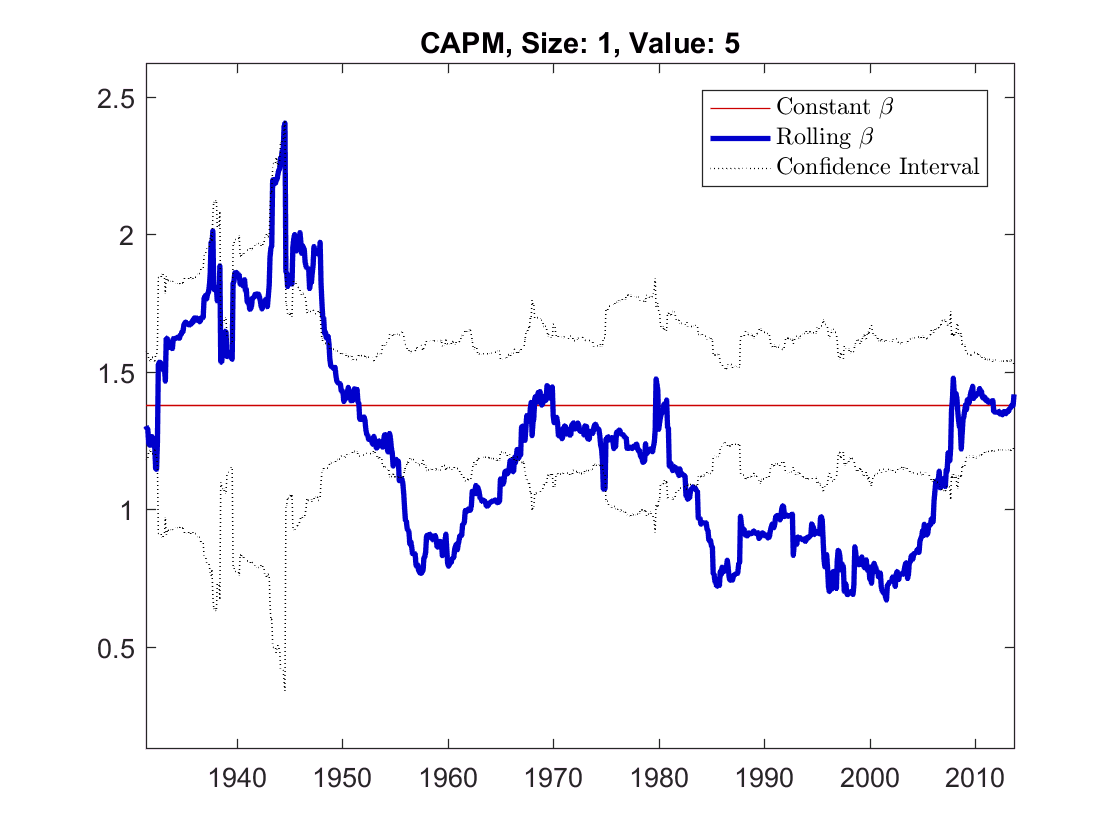

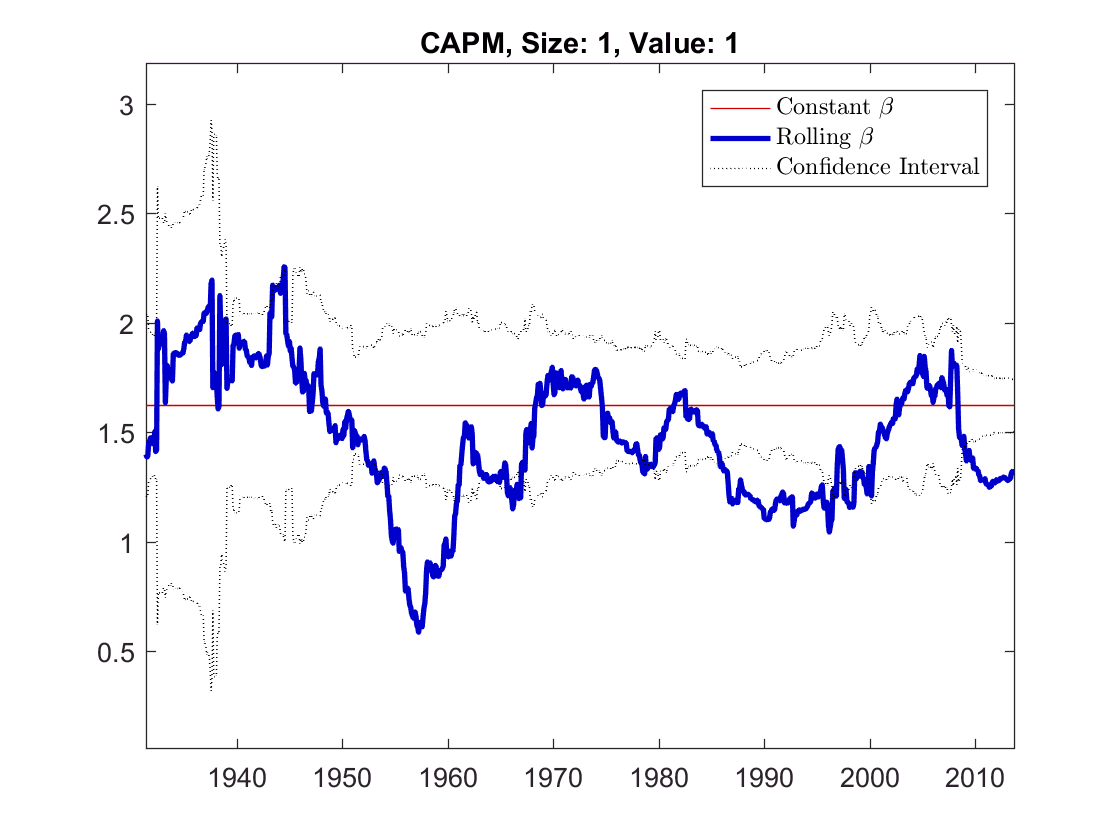

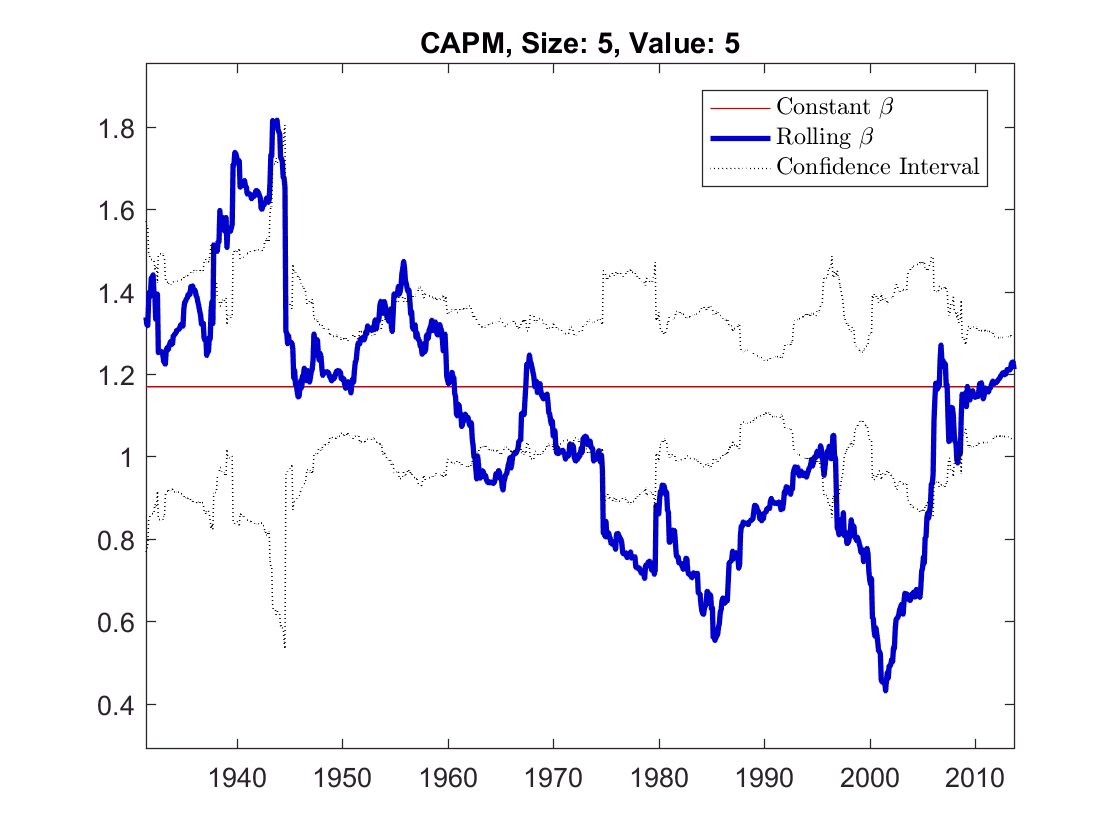

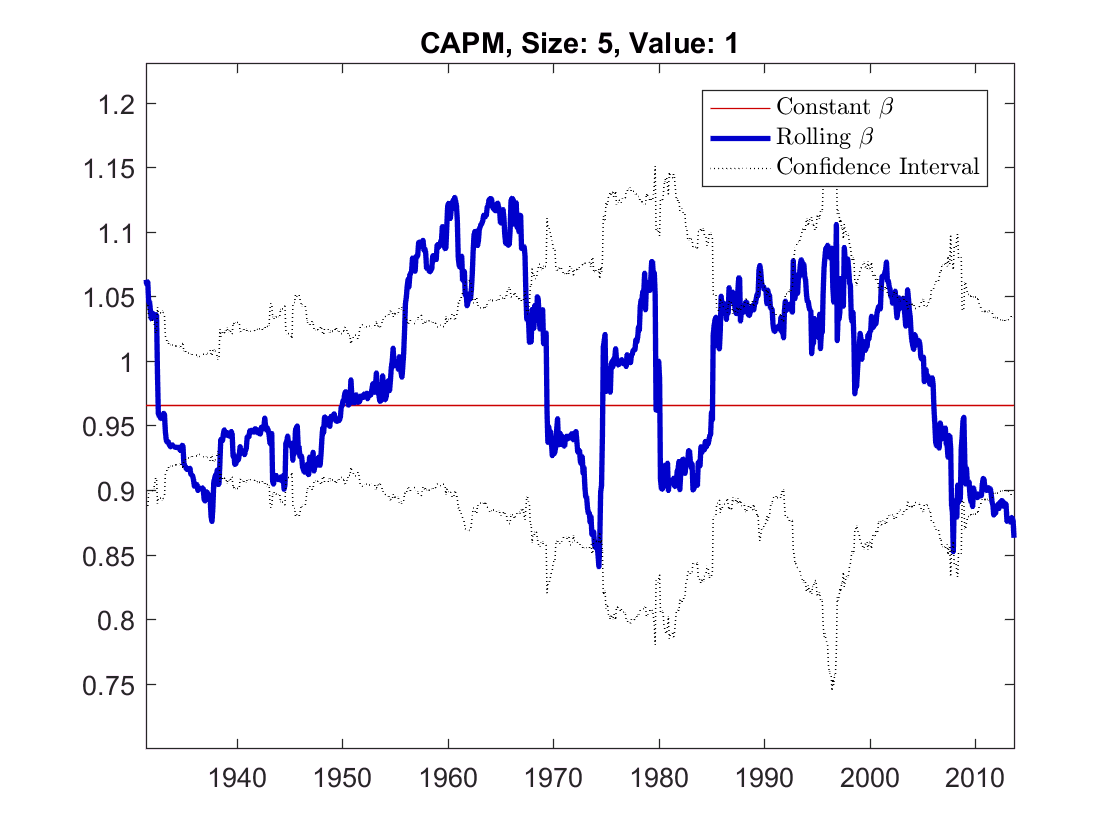

% Regressor is not only the market
X = FF_factors_monthly(:,2);
% Remove bad observations
X = X(~pl,:);
% Loop over the 4 series
for i=1:4
    y = ys(:,i);
    % Full sample estimates
    b_full_sample = ols(y,X,1);
    
    se_roll = zeros(2,T);
    b_roll = zeros(2,T);
    for t=60:T
        X_roll = X(t-59:t,:);
        y_roll = y(t-59:t);
        [b_roll(:,t),~,~,~,VCV_white]=ols(y_roll,X_roll,1);
        se_roll(:,t) = sqrt(diag(VCV_white));
    end
    
    b_ci_plus = b_full_sample(2) +  1.96*se_roll(2,:);
    b_ci_minus = b_full_sample(2) - 1.96*se_roll(2,:);
    % Open a new figure
    figure(i+10)
    plot_data = [b_full_sample(2)*ones(T,1) b_roll(2,:)' b_ci_plus' b_ci_minus'];
    % Remove first 59 data points
    plot_data = plot_data(60:end,:);
    dates = FF_mldates(60:end);
    % Plot
    h = plot(dates,plot_data);
    % Set axis to appear nice
    axis tight;
    ax = axis;
    sp = ax(4) - ax(3);
    ax(3) = ax(3) - .1 * sp;
    ax(4) = ax(4) + .1 * sp;
    axis(ax);
    % Set colors, line widths and line styles
    set(h(1),'Color',[.8 0 0])
    set(h(2),'Color',[0 0 .8],'LineWidth',2)
    set(h(3:4),'Color',[0 0 0],'LineStyle',':')
    % Set x-axis to be dates
    datetick('x','keeplimits');
    % Set the legend
    l = legend('Constant $\beta$','Rolling $\beta$','Confidence Interval');
    % Use latex to interpret strings like $\beta$
    set(l,'Interpreter','latex')
    % Set a title
    title(['CAPM, ' titles{i}]);
end

## Evidence for Size and/or Value

This example pre-computes all rolling models and then constructs the plots using the saved plot data (which is stored in a cell array, note the {} notation.

% Reinitialize X
X = FF_factors_monthly(:,2:4);
% Remove any nan observations
X = X(~pl,:);
% Set up titles to use in the figures
titles = {'Size: 1, Value: 1','Size: 1, Value: 5','Size: 5, Value: 1','Size: 5, Value: 5'};

% Loop across the 4 series
SMB = cell(4,1);
HML = cell(4,1);
for i=1:4
    % Get the "y" for a single series
    y = ys(:,i);
    % Full sample estimates
    b_full_sample = ols(y,X,1);
    % Arrays to hold rolling estimates
    se_roll = zeros(4,T);
    b_roll = zeros(4,T);
    % Loop from 60 to the end
    for t=60:T
        X_roll = X(t-59:t,:);
        y_roll = y(t-59:t);
        [b_roll(:,t),~,~,~,VCV_white]=ols(y_roll,X_roll,1);
        se_roll(:,t) = sqrt(diag(VCV_white));
    end
    % Compute beta +/- the confidence interval, market only
    
    b = b_full_sample(3);
    se = se_roll(3,:)';
    SMB{i} = [b*ones(T,1) b_roll(3,:)' b+1.96*se b-1.96*se];
    b = b_full_sample(4);
    se = se_roll(4,:)';
    HML{i} = [b*ones(T,1) b_roll(4,:)' b+1.96*se b-1.96*se];
end

## Plotting

Plotting uses the same code as above once plot_data is assigned to an element of the SMB or HML cell array

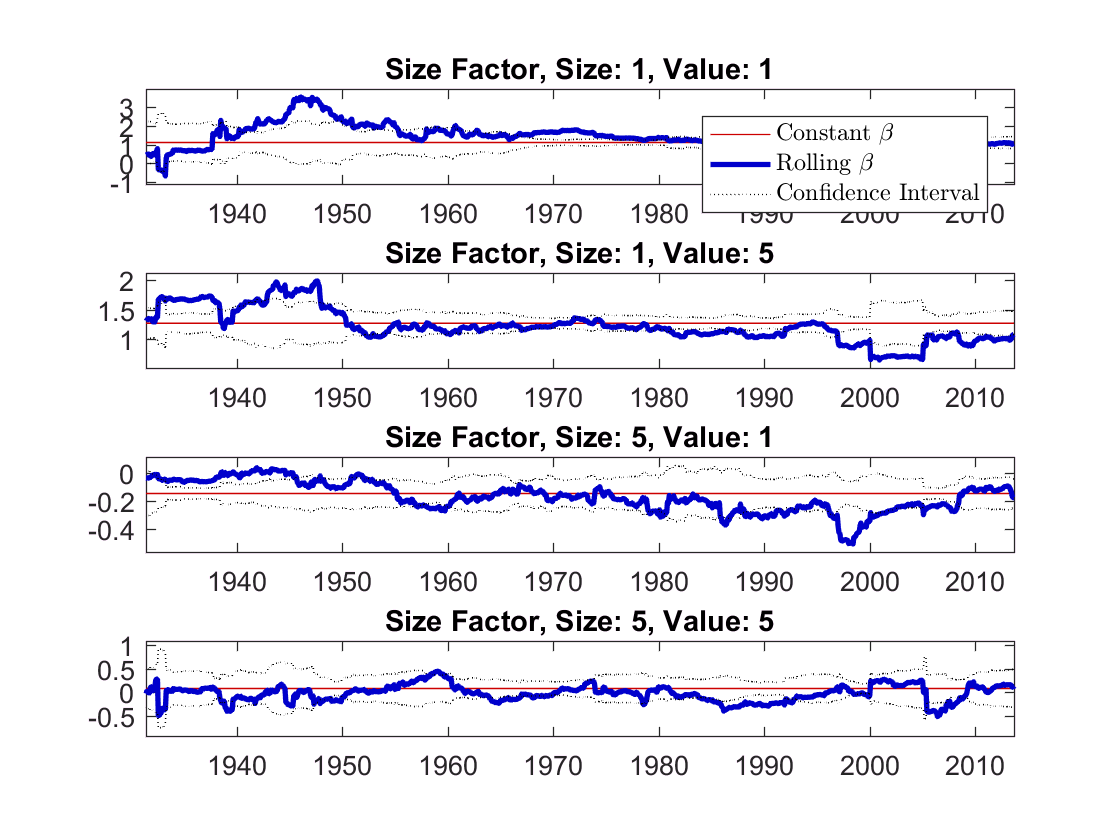

% New figure
figure(97)
% Loop over series
for i=1:4
    % Use a subplot, note the i
    subplot(4,1,i)
    % Set the plot data
    plot_data = SMB{i};
    plot_data = plot_data(60:end,:);
    % Do the same for the dates
    dates = FF_mldates(60:end);
    % Plot
    h = plot(dates,plot_data);
    % Set axis to appear nice
    axis tight;
    ax = axis;
    sp = ax(4) - ax(3);
    ax(3) = ax(3) - .1 * sp;
    ax(4) = ax(4) + .1 * sp;
    axis(ax);
    % Set colors, line widths and line styles
    set(h(1),'Color',[.8 0 0])
    set(h(2),'Color',[0 0 .8],'LineWidth',2)
    set(h(3:4),'Color',[0 0 0],'LineStyle',':')
    % Set x-axis to be dates
    datetick('x','keeplimits');
    if i==1 % Only in the 1st plot
        % Set the legend
        l = legend('Constant $\beta$','Rolling $\beta$','Confidence Interval');
        % Use latex to interpret strings like $\beta$
        set(l,'Interpreter','latex')
    end
    % Set a title
    title(['Size Factor, ' titles{i}]);
end

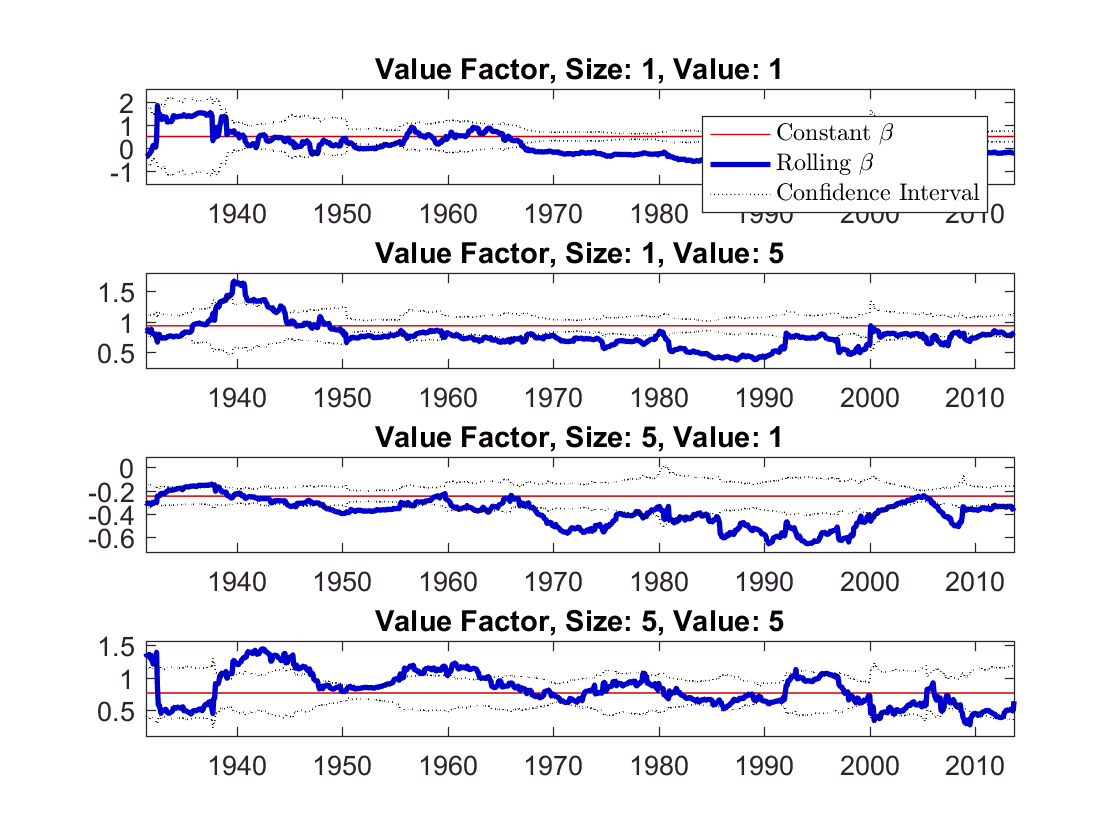



% New figure
figure(98)
% Loop over series
for i=1:4
    % Use a subplot, note the i
    subplot(4,1,i)
    % Set the plot data
    plot_data = HML{i};
    % Remove first 59 points, which are 0
    plot_data = plot_data(60:end,:);
    % Do the same for the dates
    dates = FF_mldates(60:end);
    % Plot
    h = plot(dates,plot_data);
    % Set axis to appear nice
    axis tight;
    ax = axis;
    sp = ax(4) - ax(3);
    ax(3) = ax(3) - .1 * sp;
    ax(4) = ax(4) + .1 * sp;
    axis(ax);
    % Set colors, line widths and line styles
    set(h(1),'Color',[.8 0 0])
    set(h(2),'Color',[0 0 .8],'LineWidth',2)
    set(h(3:4),'Color',[0 0 0],'LineStyle',':')
    % Set x-axis to be dates
    datetick('x','keeplimits');
    if i==1 % Only in the 1st plot
        % Set the legend
        l = legend('Constant $\beta$','Rolling $\beta$','Confidence Interval');
        % Use latex to interpret strings like $\beta$
        set(l,'Interpreter','latex')
    end
    % Set a title
    title(['Value Factor, ' titles{i}]);
end